# Estimation, Filtering and Detection

## Homework 2C: Asynchronous Sampling

## Timur Uzakov

## MACROS

clear all;

## Problem 1:

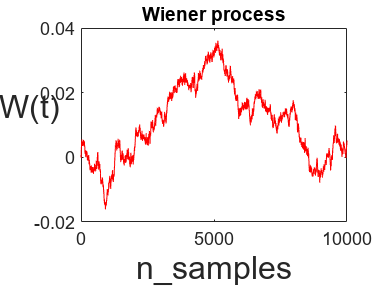

% Parameters
n_seconds = 1000;
Ts = 20;
sigma_e = 0.01;
sigma_process = 0.1;
tau = 50; % 50 seconds

% Continuous Wiener Process
dt = 0.1;

N = n_seconds/0.1;
dW = zeros(1,N);                
W = zeros(1,N);                 
dW(1) = 0.001*sqrt(dt)*randn();    
W(1) = dW(1);                  
for j = 2:N
    dW(j)= 0.001*sqrt(dt)*randn();
    W(j) = W(j-1) + dW(j);
end
f = gcf;

plot([1:1:n_seconds/dt],W,'r-')     
xlabel('n\_samples','FontSize',16)
ylabel('W(t)','FontSize',16,'Rotation',0)
title("Wiener process");
ind = 1;
exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);

ind = ind + 1;
W_continuous = W;
% mean and variance

% Wiener Process (discrete signal)
dt = Ts;
W_discrete = zeros(1,n_seconds/Ts); 
N = n_seconds/Ts;         
for j = 1:n_seconds/Ts
    W_discrete(j) = W(j*Ts/0.1);
end

% Continuous-time system
% . 
% x = Ax + Bu + Gd  + w      {State equation}
% y = Cx + Du + 0*d + v      {Measurements}

[A,B,C,D] = tf2ss(1,[tau^2 2*tau 1]);
G = [1;0];
B = [B G];
D = [D 0];
sys = ss(A,B,C,D);
u_continuous = ones(1,n_seconds/0.1);
continuous_signal_y = lsim(sys,[u_continuous;W_continuous],[0.1:0.1:n_seconds]) + sigma_e*randn;

% f = gcf;
% step(sys);
% title("Step response of the continous time system");
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
ind = ind + 1;
% f = gcf;
% plot([0.1:0.1:n_seconds],continuous_signal_y);
% title("Continuous-time signal of temperature");
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
ind = ind +1;
% Discrete-time system
dsys = c2d(sys,Ts,'tustin');
% f = gcf;
% step(dsys);
% title("Step response of the discrete time system");
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
ind = ind + 1;
Ad = dsys.A;
Bd = dsys.B;
Cd = dsys.C;
Dd = dsys.D;
disturbance = W_discrete;

x = zeros(2,n_seconds/Ts);
y = zeros(1,n_seconds/Ts);
u = ones(1,n_seconds/Ts);

for i=1:(n_seconds/Ts-1)
    x(:,i+1) = Ad*x(:,i) + Bd*[u(i);disturbance(i)] + sigma_process.*randn(2,1);
    y(:,i)   = Cd*x(:,i) + Dd*[u(i);disturbance(i)] + sigma_e*randn(1,1);
end
% f = gcf;
% plot([1:20:n_seconds], y)
% ylabel("Amplitude");
% xlabel("Time (seconds)");
% title("Step input stochastic-discrete-model response");
% exportgraphics(f,'fig5.png','Resolution',1000);

## Problem 2:

% Synchronous sampling
Tc = Ts;
etta = (Ts-Tc)/Ts;
Rc = sigma_e^2;
Qc = [0.000000000000001*sigma_process^2 0.000001*sigma_process^2;0.000001*sigma_process^2 sigma_process^2];

A11 = A(1,1);
A12 = A(1,2);
A21 = A(2,1);
A22 = A(2,2);

A_sync = expm(A*Ts);
B_int = [(exp(A11*Ts)-exp(A11*0))/A11 (exp(A12*Ts)-exp(A12*0))/A12;(exp(A21*Ts)-exp(0))/A21 Ts];
B_sync = B_int*B;

C_sync = C*expm(A*etta*Ts);


Q11 = Qc(1,1);
Q12 = Qc(1,2);
Q21 = Qc(2,1);
Q22 = Qc(2,2);

C11 = C(1,1);
C12 = C(1,2);

% resulting polynomial matrix
% Q ... expm(A*x)*Qc*expm(A'*x)
%[exp(A11*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A12*x)*(Q12*exp(A11*x) + Q22*exp(A12*x)), exp(A21*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A22*x)*(Q12*exp(A11*x) + Q22*exp(A12*x))]
%[exp(A11*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A12*x)*(Q12*exp(A21*x) + Q22*exp(A22*x)), exp(A21*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A22*x)*(Q12*exp(A21*x) + Q22*exp(A22*x))]
% expand...
% Q11 ---- Q11*exp(2*A11*x) + Q22*exp(2*A12*x) + Q12*exp(A11*x)*exp(A12*x) + Q21*exp(A11*x)*exp(A12*x)
% Q12 ---- Q11*exp(A11*x)*exp(A21*x) + Q12*exp(A11*x)*exp(A22*x) + Q21*exp(A12*x)*exp(A21*x) + Q22*exp(A12*x)*exp(A22*x)
% Q21 ---- Q11*exp(A11*x)*exp(A21*x) + Q12*exp(A12*x)*exp(A21*x) + Q21*exp(A11*x)*exp(A22*x) + Q22*exp(A12*x)*exp(A22*x)
% Q22 ---- Q11*exp(2*A21*x) + Q22*exp(2*A22*x) + Q12*exp(A21*x)*exp(A22*x) + Q21*exp(A21*x)*exp(A22*x)


funQ11 = @(x) Q11*exp(2*A11*x)+Q22*exp(2*A12*x) + Q12*exp((A11+A12)*x) + Q21*exp((A11+A12)*x);
funQ12 = @(x) Q11*exp((A11+A21)*x)+Q12*exp((A11+A22)*x) + Q21*exp((A12+A21)*x) + Q22*exp((A12+A22)*x);
funQ21 = @(x) Q11*exp((A11+A21)*x)+Q12*exp((A12+A21)*x) + Q21*exp((A11+A22)*x) + Q22*exp((A12+A22)*x);
funQ22 = @(x) Q11*exp(2*A21*x)+Q22*exp(2*A22*x) + Q12*exp((A22+A21)*x) + Q21*exp((A21+A22)*x);

Qint11 = integral(funQ11,0,Ts);
Qint12 = integral(funQ12,0,Ts);
Qint21 = integral(funQ21,0,Ts);
Qint22 = Q11*(exp(2*A21*Ts)-exp(0))/(2*A21)+Q22*Ts + Q12*exp(((A22+A21)*Ts)-exp(0))/(A22+A21) + Q21*exp(((A21+A22)*Ts)-exp(0))/(A21+A22);


Q_sync = [Qint11 Qint12; Qint21 Qint22];
% resulting polynomial matrix
% R ...  C*expm(A*x)*Qc*expm(A'*x)*C'
% C11*(exp(A11*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A12*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x)))) + C12*(exp(A21*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A22*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x))))
% expand ...
funR = @(x) C11^2*Q11*exp(2*A11*x) + C12^2*Q11*exp(2*A21*x) + C11^2*Q22*exp(2*A12*x) + C12^2*Q22*exp(2*A22*x) + C11^2*Q12*exp((A11+A12)*x) + C11^2*Q21*exp((A11+A12)*x) + C12^2*Q12*exp((A21+A22)*x) + C12^2*Q21*exp((A21+A22)*x) + 2*C11*C12*Q11*exp((A11+A21)*x) + C11*C12*Q12*exp((A11+A22)*x) + C11*C12*Q12*exp((A12+A21)*x) + C11*C12*Q21*exp((A11+A22)*x) + C11*C12*Q21*exp((A12+A21)*x) + 2*C11*C12*Q22*exp((A12+A22)*x);

R_int = integral(funR,0,etta*Ts); 

R_sync = R_int + Rc;

% resulting polynomial matrix
% S ...  expm(A*x)*Qc*expm(A'*x)*C'
% C11*(exp(A11*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A12*x)*(Q12*exp(A11*x) + Q22*exp(A12*x))) + C12*(exp(A21*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A22*x)*(Q12*exp(A11*x) + Q22*exp(A12*x)))
% C11*(exp(A11*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A12*x)*(Q12*exp(A21*x) + Q22*exp(A22*x))) + C12*(exp(A21*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A22*x)*(Q12*exp(A21*x) + Q22*exp(A22*x)))
% expand ...
% C11*Q11*exp(2*A11*x) + C11*Q22*exp(2*A12*x) + C11*Q12*exp(A11*x)*exp(A12*x) + C11*Q21*exp(A11*x)*exp(A12*x) + C12*Q11*exp(A11*x)*exp(A21*x) + C12*Q12*exp(A11*x)*exp(A22*x) + C12*Q21*exp(A12*x)*exp(A21*x) + C12*Q22*exp(A12*x)*exp(A22*x)
% C12*Q11*exp(2*A21*x) + C12*Q22*exp(2*A22*x) + C11*Q11*exp(A11*x)*exp(A21*x) + C11*Q12*exp(A12*x)*exp(A21*x) + C11*Q21*exp(A11*x)*exp(A22*x) + C11*Q22*exp(A12*x)*exp(A22*x) + C12*Q12*exp(A21*x)*exp(A22*x) + C12*Q21*exp(A21*x)*exp(A22*x)

funS11 = @(x) C11*Q11*exp(2*A11*x) + C11*Q22*exp(2*A12*x) + C11*Q12*exp((A11+A12)*x) + C11*Q21*exp((A11+A12)*x) + C12*Q11*exp((A11+A21)*x) + C12*Q12*exp((A11+A22)*x) + C12*Q21*exp((A12+A21)*x) + C12*Q22*exp((A12+A22)*x);
funS21 = @(x) C12*Q11*exp(2*A21*x) + C12*Q22*exp(2*A22*x) + C11*Q11*exp((A11+A21)*x) + C11*Q12*exp((A12+A21)*x) + C11*Q21*exp((A11+A22)*x) + C11*Q22*exp((A12+A22)*x) + C12*Q12*exp((A21+A22)*x) + C12*Q21*exp((A21+A22)*x);
Sint11 = integral(funS11,0,etta*Ts); 
Sint21 = integral(funS21,0,etta*Ts);

S_sync = [Sint11 ; Sint21];

% resulting polynomial matrix
% D ...  expm(A*x)
% [exp(A11*x) exp(A12*x)]
% [exp(A21*x) exp(A22*x)]

funD11 = @(x) exp(A11*x);
funD12 = @(x) exp(A12*x);
funD21 = @(x) exp(A21*x);
funD22 = @(x) exp(A22*x);

Dint11 = integral(funD11,0,etta*Ts); 
Dint12 = integral(funD12,0,etta*Ts); 
Dint21 = integral(funD21,0,etta*Ts); 
Dint22 = integral(funD22,0,etta*Ts); 

Dint = [Dint11 Dint12; Dint21 Dint22];
D_sync = C*Dint*B;

% Syncronous KF
P_pred = [1 10;10 300];

xhat = zeros(2, N);

P_pred_eig = zeros(2, N);
P_pred_eig(:,1) = eig(P_pred);

P_corr_eig = zeros(2, N);

y_hat = zeros(1,n_seconds/Ts);

for i = 1:N-1
    % Filtering
    % Correction step
    % innovation
    r = y(:,i) - C_sync*xhat(:, i);
    % residual covariance
    S = C_sync*P_pred*C_sync' + R_sync;
    % Kalman gain
    W = P_pred*C_sync'/S;
    % update
    xhat(:, i) = xhat(:, i) + W*r; 
    P_corr = P_pred - W*C_sync*P_pred;
    % P(t|t)
    P_corr_eig(:,i) = eig(P_corr);

    % Prediction step
    xhat(:, i+1) = A_sync*xhat(:,i); + B_sync*u(:,i);
    P_pred = A_sync*P_corr*A_sync' + Q_sync;
    % P(t+1|t)
    P_pred_eig(:,i+1) = eig(P_pred);
end
P_sync_pred = P_pred

P_sync_pred =     0.2158    6.1132
    6.1132  326.6278


P_sync_corr = P_corr

P_sync_corr =     0.1765    4.0150
    4.0150  214.5191



% f = gcf;
% plot([1:20:n_seconds], C_sync*xhat)
% hold on
% plot([0.1:0.1:n_seconds], continuous_signal_y);
% hold off
% ylabel("Amplitude");
% xlabel("Time (seconds)");
% title("Estimated temperature from sync KF");
% legend("estimated y", "ground truth");
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
% ind = ind + 1;
% f = gcf;
% plot([1:20:n_seconds], P_pred_eig(1,:));
% hold on 
% plot([1:20:n_seconds], P_corr_eig(1,:));
% hold off
% ylabel("Value");
% xlabel("Time (seconds)");
% legend("pred\_eig\_1","corr\_eig\_1");
% title("Eigen values of prediction and corr0ection covariance from sync KF");
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
% ind = ind + 1;
% f = gcf;
% plot([1:20:n_seconds], P_pred_eig(2,:));
% hold on
% plot([1:20:n_seconds], P_corr_eig(2,:));
% hold off
% ylabel("Value");
% xlabel("Time (seconds)");
% legend("pred\_eig\_2","corr\_eig\_2");
% title("Eigen values of prediction and correction covariance from sync KF");
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
% ind = ind +1;

## Problem 3:

P_async_pred =     0.2127    6.0712
    6.0712  276.0022


P_async_corr =     0.1535    3.6071
    3.6071  173.3961


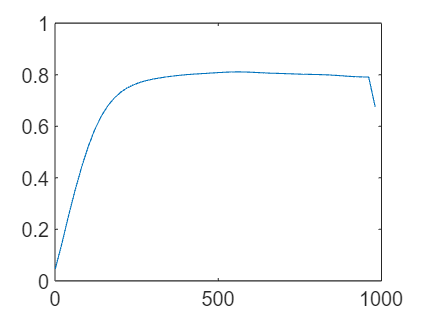

P_async_pred =     0.2111    6.0427
    6.0427  256.0065


P_async_corr =     0.1426    3.4449
    3.4449  157.5460


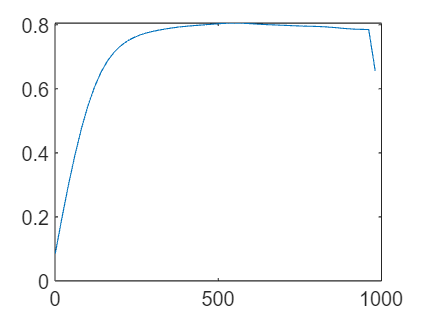

P_async_pred =     0.2112    6.0390
    6.0390  256.1880


P_async_corr =     0.1425    3.4407
    3.4407  157.8983


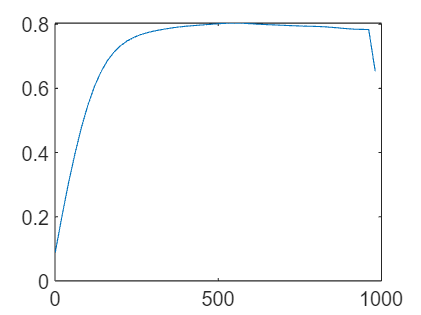

% Asynchrounous sampling with a set of 3 Kalman filter models
Tcs = [100 10 1]; % time in samples, because 0.1 cannot be represented in samples of Wiener process
N = n_seconds/Ts;
yhat_10 = zeros(2, N);
yhat_1 = zeros(2, N);
yhat_01 = zeros(2, N);
Rc = sigma_e^2;
Qc = [0.000000000000001*sigma_process^2 0.000001*sigma_process^2;0.000001*sigma_process^2 sigma_process^2];


MSE = zeros(1, 3);
for j = 1:3
    Tc = Tcs(j);
    %% Measuring at different points 
    y_meas = zeros(1,n_seconds/Ts);
    for i=2:n_seconds/Ts
        y_meas(i-1) = continuous_signal_y(i*Ts*10-Tc); % this is why Tcs is multiplied by 10 times
    end

    % KF
    etta = (Ts-Tc*0.1)/Ts;
    Rc = sigma_e^2;
    Qc = [0.000000000000001*sigma_process^2 0.000001*sigma_process^2;0.000001*sigma_process^2 sigma_process^2];

    
    A11 = A(1,1);
    A12 = A(1,2);
    A21 = A(2,1);
    A22 = A(2,2);

    A_async = A_sync;
    B_async = B_sync;
    
    % noise properties


    C_async = C*expm(A*etta*Ts);
    
    
    Q11 = Qc(1,1);
    Q12 = Qc(1,2);
    Q21 = Qc(2,1);
    Q22 = Qc(2,2);
    
    C11 = C(1,1);
    C12 = C(1,2);
    
    % resulting polynomial matrix
    % Q ... expm(A*x)*Qc*expm(A'*x)
    %[exp(A11*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A12*x)*(Q12*exp(A11*x) + Q22*exp(A12*x)), exp(A21*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A22*x)*(Q12*exp(A11*x) + Q22*exp(A12*x))]
    %[exp(A11*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A12*x)*(Q12*exp(A21*x) + Q22*exp(A22*x)), exp(A21*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A22*x)*(Q12*exp(A21*x) + Q22*exp(A22*x))]
    
    funQ11 = @(x) Q11*exp(2*A11*x)+Q22*exp(2*A12*x) + Q12*exp((A11+A12)*x) + Q21*exp((A11+A12)*x);
    funQ12 = @(x) Q11*exp((A11+A21)*x)+Q12*exp((A11+A22)*x) + Q21*exp((A12+A21)*x) + Q22*exp((A12+A22)*x);
    funQ21 = @(x) Q11*exp((A11+A21)*x)+Q12*exp((A12+A21)*x) + Q21*exp((A11+A22)*x) + Q22*exp((A12+A22)*x);
    funQ22 = @(x) Q11*exp(2*A21*x)+Q22*exp(2*A22*x) + Q12*exp((A22+A21)*x) + Q21*exp((A21+A22)*x);
    
    Qint11 = integral(funQ11,0,Ts);
    Qint12 = integral(funQ12,0,Ts);
    Qint21 = integral(funQ21,0,Ts);
    Qint22 = Q11*(exp(2*A21*Ts)-exp(0))/(2*A21)+Q22*Ts + Q12*exp(((A22+A21)*Ts)-exp(0))/(A22+A21) + Q21*exp(((A21+A22)*Ts)-exp(0))/(A21+A22);
    
    Q_async = [Qint11 Qint12; Qint21 Qint22];
    % resulting polynomial matrix
    % R ...  C*expm(A*x)*Qc*expm(A'*x)*C'
    % C11*(exp(A11*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A12*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x)))) + C12*(exp(A21*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A22*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x))))
    % expand ...
    funR = @(x) C11^2*Q11*exp(2*A11*x) + C12^2*Q11*exp(2*A21*x) + C11^2*Q22*exp(2*A12*x) + C12^2*Q22*exp(2*A22*x) + C11^2*Q12*exp((A11+A12)*x) + C11^2*Q21*exp((A11+A12)*x) + C12^2*Q12*exp((A21+A22)*x) + C12^2*Q21*exp((A21+A22)*x) + 2*C11*C12*Q11*exp((A11+A21)*x) + C11*C12*Q12*exp((A11+A22)*x) + C11*C12*Q12*exp((A12+A21)*x) + C11*C12*Q21*exp((A11+A22)*x) + C11*C12*Q21*exp((A12+A21)*x) + 2*C11*C12*Q22*exp((A12+A22)*x);
    
    R_int = integral(funR,0,etta*Ts); 
    
    R_async = R_int + Rc;
    
    % resulting polynomial matrix
    % S ...  expm(A*x)*Qc*expm(A'*x)*C'
    % C11*(exp(A11*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A12*x)*(Q12*exp(A11*x) + Q22*exp(A12*x))) + C12*(exp(A21*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A22*x)*(Q12*exp(A11*x) + Q22*exp(A12*x)))
    % C11*(exp(A11*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A12*x)*(Q12*exp(A21*x) + Q22*exp(A22*x))) + C12*(exp(A21*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A22*x)*(Q12*exp(A21*x) + Q22*exp(A22*x)))
    % expand ...
    % C11*Q11*exp(2*A11*x) + C11*Q22*exp(2*A12*x) + C11*Q12*exp(A11*x)*exp(A12*x) + C11*Q21*exp(A11*x)*exp(A12*x) + C12*Q11*exp(A11*x)*exp(A21*x) + C12*Q12*exp(A11*x)*exp(A22*x) + C12*Q21*exp(A12*x)*exp(A21*x) + C12*Q22*exp(A12*x)*exp(A22*x)
    % C12*Q11*exp(2*A21*x) + C12*Q22*exp(2*A22*x) + C11*Q11*exp(A11*x)*exp(A21*x) + C11*Q12*exp(A12*x)*exp(A21*x) + C11*Q21*exp(A11*x)*exp(A22*x) + C11*Q22*exp(A12*x)*exp(A22*x) + C12*Q12*exp(A21*x)*exp(A22*x) + C12*Q21*exp(A21*x)*exp(A22*x)
    
    funS11 = @(x) C11*Q11*exp(2*A11*x) + C11*Q22*exp(2*A12*x) + C11*Q12*exp((A11+A12)*x) + C11*Q21*exp((A11+A12)*x) + C12*Q11*exp((A11+A21)*x) + C12*Q12*exp((A11+A22)*x) + C12*Q21*exp((A12+A21)*x) + C12*Q22*exp((A12+A22)*x);
    funS21 = @(x) C12*Q11*exp(2*A21*x) + C12*Q22*exp(2*A22*x) + C11*Q11*exp((A11+A21)*x) + C11*Q12*exp((A12+A21)*x) + C11*Q21*exp((A11+A22)*x) + C11*Q22*exp((A12+A22)*x) + C12*Q12*exp((A21+A22)*x) + C12*Q21*exp((A21+A22)*x);
    Sint11 = integral(funS11,0,etta*Ts); 
    Sint21 = integral(funS21,0,etta*Ts);
    
    S_async = [Sint11 ; Sint21];
    
    % resulting polynomial matrix
    % D ...  expm(A*x)
    % [exp(A11*x) exp(A12*x)]
    % [exp(A21*x) exp(A22*x)]
    
    funD11 = @(x) exp(A11*x);
    funD12 = @(x) exp(A12*x);
    funD21 = @(x) exp(A21*x);
    funD22 = @(x) exp(A22*x);
    
    Dint11 = integral(funD11,0,etta*Ts); 
    Dint12 = integral(funD12,0,etta*Ts); 
    Dint21 = integral(funD21,0,etta*Ts); 
    Dint22 = integral(funD22,0,etta*Ts); 
    
    Dint = [Dint11 Dint12; Dint21 Dint22];
    D_async = C*Dint*B;



    % initial conditions
    P_pred = [1 10;10 300];
    xhat = zeros(2, N);
    P_pred_eig = zeros(2, N);
    P_pred_eig(:,1) = eig(P_pred);
    P_corr_eig = zeros(2, N);
    y_hat = zeros(1,n_seconds/Ts);
    
    % main loop
    for i = 1:N-1
        % Filtering
        % Correction step
        % innovation
        r = y_meas(:,i) - C_async*xhat(:, i);
        % residual covariance
        S = C_async*P_pred*C_async' + R_async;
        % Kalman gain
        W = P_pred*C_async'/S;
        % update
        xhat(:, i) = xhat(:, i) + W*r; 
        P_corr = P_pred - W*C_async*P_pred;
        % P(t|t)
        P_corr_eig(:,i) = eig(P_corr);
    
        % Prediction step
        xhat(:, i+1) = A_async*xhat(:,i); + B_async*u(:,i);
        P_pred = A_async*P_corr*A_async' + Q_async;
        % P(t+1|t)
        P_pred_eig(:,i+1) = eig(P_pred);
    end
    P_async_pred = P_pred
    P_async_corr = P_corr

    if (j == 1)
        yhat_10 = C_async*xhat;
        P_pred_10 = P_pred;
        P_corr_10 = P_corr;
    end
    if (j == 2)
        yhat_1 = C_async*xhat;
        P_pred_1 = P_pred;
        P_corr_1 = P_corr;
    end
    if (j == 3)
        yhat_01 = C_async*xhat;
        P_pred_01 = P_pred;
        P_corr_01 = P_corr;
    end
%     
%     f = gcf;
      figure();
      plot([1:20:n_seconds], C_async*xhat)
%     hold on
%     plot([0.1:0.1:n_seconds], continuous_signal_y);
%     hold off
%     ylabel("Amplitude");
%     xlabel("Time (seconds)");
%     legend("estimated y", "ground truth");
%     title(["Estimated temperature from async KF Tc:" num2str(Tc*0.1)]);
%     exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
%     ind = ind+1;
%     disp("Tc")
%     disp(Tc*0.1)
%     disp("Prediciton values")
%     disp(P_pred)
%     disp("Correction values")
%     disp(P_corr)
%    
%     
%     f = gcf;
%     plot([1:20:n_seconds], P_pred_eig(1,:));
%     ylabel("Value");
%     xlabel("Time (seconds)");
%     legend("pred\_eig\_1");
%     title(["Eigen value of prediction covariance from async KF  Tc:" num2str(Tc*0.1)]);
%     exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
%     ind = ind+1;
%     f = gcf;
%     plot([1:20:n_seconds], P_pred_eig(2,:));
%     ylabel("Value");
%     xlabel("Time (seconds)");
%     legend("pred\_eig\_2");
%     title(["Eigen value of prediction covariance async KF  Tc:" num2str(Tc*0.1)]);
%     exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
%     ind = ind+1;
%     MSE(j) = calculateMSE(C_async*xhat,y_meas);
end

## Problem 4.1:

% Show impact of neglecting S in case of asynchronous sampling - method 1
Tcs = [100 10 1];
Tc = Tcs(3);
etta = (Ts-Tc*0.1)/Ts;
Qc = [0.000000000000001*sigma_process^2 0.000000*sigma_process^2;0.000000*sigma_process^2 sigma_process^2];


% noise properties
A11 = A(1,1);
A12 = A(1,2);
A21 = A(2,1);
A22 = A(2,2);

A_async = A_sync;
B_async = B_sync;

% noise properties


C_async = C*expm(A*etta*Ts);


Q11 = Qc(1,1);
Q12 = Qc(1,2);
Q21 = Qc(2,1);
Q22 = Qc(2,2);

C11 = C(1,1);
C12 = C(1,2);

% resulting polynomial matrix
% Q ... expm(A*x)*Qc*expm(A'*x)
%[exp(A11*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A12*x)*(Q12*exp(A11*x) + Q22*exp(A12*x)), exp(A21*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A22*x)*(Q12*exp(A11*x) + Q22*exp(A12*x))]
%[exp(A11*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A12*x)*(Q12*exp(A21*x) + Q22*exp(A22*x)), exp(A21*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A22*x)*(Q12*exp(A21*x) + Q22*exp(A22*x))]

funQ11 = @(x) Q11*exp(2*A11*x)+Q22*exp(2*A12*x) + Q12*exp((A11+A12)*x) + Q21*exp((A11+A12)*x);
funQ12 = @(x) Q11*exp((A11+A21)*x)+Q12*exp((A11+A22)*x) + Q21*exp((A12+A21)*x) + Q22*exp((A12+A22)*x);
funQ21 = @(x) Q11*exp((A11+A21)*x)+Q12*exp((A12+A21)*x) + Q21*exp((A11+A22)*x) + Q22*exp((A12+A22)*x);
funQ22 = @(x) Q11*exp(2*A21*x)+Q22*exp(2*A22*x) + Q12*exp((A22+A21)*x) + Q21*exp((A21+A22)*x);

Qint11 = integral(funQ11,0,Ts);
Qint12 = integral(funQ12,0,Ts);
Qint21 = integral(funQ21,0,Ts);
Qint22 = Q11*(exp(2*A21*Ts)-exp(0))/(2*A21)+Q22*Ts + Q12*exp(((A22+A21)*Ts)-exp(0))/(A22+A21) + Q21*exp(((A21+A22)*Ts)-exp(0))/(A21+A22);


Q_async = [Qint11 Qint12; Qint21 Qint22];
% resulting polynomial matrix
% R ...  C*expm(A*x)*Qc*expm(A'*x)*C'
% C11*(exp(A11*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A12*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x)))) + C12*(exp(A21*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A22*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x))))
% expand ...
funR = @(x) C11^2*Q11*exp(2*A11*x) + C12^2*Q11*exp(2*A21*x) + C11^2*Q22*exp(2*A12*x) + C12^2*Q22*exp(2*A22*x) + C11^2*Q12*exp((A11+A12)*x) + C11^2*Q21*exp((A11+A12)*x) + C12^2*Q12*exp((A21+A22)*x) + C12^2*Q21*exp((A21+A22)*x) + 2*C11*C12*Q11*exp((A11+A21)*x) + C11*C12*Q12*exp((A11+A22)*x) + C11*C12*Q12*exp((A12+A21)*x) + C11*C12*Q21*exp((A11+A22)*x) + C11*C12*Q21*exp((A12+A21)*x) + 2*C11*C12*Q22*exp((A12+A22)*x);

R_int = integral(funR,0,etta*Ts); 

R_async = R_int + Rc;

% resulting polynomial matrix
% S ...  expm(A*x)*Qc*expm(A'*x)*C'
% C11*(exp(A11*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A12*x)*(Q12*exp(A11*x) + Q22*exp(A12*x))) + C12*(exp(A21*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A22*x)*(Q12*exp(A11*x) + Q22*exp(A12*x)))
% C11*(exp(A11*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A12*x)*(Q12*exp(A21*x) + Q22*exp(A22*x))) + C12*(exp(A21*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A22*x)*(Q12*exp(A21*x) + Q22*exp(A22*x)))
% expand ...
% C11*Q11*exp(2*A11*x) + C11*Q22*exp(2*A12*x) + C11*Q12*exp(A11*x)*exp(A12*x) + C11*Q21*exp(A11*x)*exp(A12*x) + C12*Q11*exp(A11*x)*exp(A21*x) + C12*Q12*exp(A11*x)*exp(A22*x) + C12*Q21*exp(A12*x)*exp(A21*x) + C12*Q22*exp(A12*x)*exp(A22*x)
% C12*Q11*exp(2*A21*x) + C12*Q22*exp(2*A22*x) + C11*Q11*exp(A11*x)*exp(A21*x) + C11*Q12*exp(A12*x)*exp(A21*x) + C11*Q21*exp(A11*x)*exp(A22*x) + C11*Q22*exp(A12*x)*exp(A22*x) + C12*Q12*exp(A21*x)*exp(A22*x) + C12*Q21*exp(A21*x)*exp(A22*x)

funS11 = @(x) C11*Q11*exp(2*A11*x) + C11*Q22*exp(2*A12*x) + C11*Q12*exp((A11+A12)*x) + C11*Q21*exp((A11+A12)*x) + C12*Q11*exp((A11+A21)*x) + C12*Q12*exp((A11+A22)*x) + C12*Q21*exp((A12+A21)*x) + C12*Q22*exp((A12+A22)*x);
funS21 = @(x) C12*Q11*exp(2*A21*x) + C12*Q22*exp(2*A22*x) + C11*Q11*exp((A11+A21)*x) + C11*Q12*exp((A12+A21)*x) + C11*Q21*exp((A11+A22)*x) + C11*Q22*exp((A12+A22)*x) + C12*Q12*exp((A21+A22)*x) + C12*Q21*exp((A21+A22)*x);
Sint11 = integral(funS11,0,etta*Ts); 
Sint21 = integral(funS21,0,etta*Ts);

S_async = [Sint11 ; Sint21];

% resulting polynomial matrix
% D ...  expm(A*x)
% [exp(A11*x) exp(A12*x)]
% [exp(A21*x) exp(A22*x)]

funD11 = @(x) exp(A11*x);
funD12 = @(x) exp(A12*x);
funD21 = @(x) exp(A21*x);
funD22 = @(x) exp(A22*x);

Dint11 = integral(funD11,0,etta*Ts); 
Dint12 = integral(funD12,0,etta*Ts); 
Dint21 = integral(funD21,0,etta*Ts); 
Dint22 = integral(funD22,0,etta*Ts); 

Dint = [Dint11 Dint12; Dint21 Dint22];
D_async = C*Dint*B;

%% Measuring at different points 
y_meas = zeros(1,n_seconds/Ts);
for i=2:n_seconds/Ts
    y_meas(i-1) = continuous_signal_y(i*Ts*10-Tc);
end

xhat = zeros(2, N);
P_pred_eig = zeros(2, N);
P_pred = [1 0;0 300];
y_hat = zeros(1,n_seconds/Ts);

P_pred_eig(:,1) = eig(P_pred);
for i = 1:N-1
    % Filtering
    % Correction step
    % innovation
    
    r = y_meas(:,i) - C_async*xhat(:, i);
    % residual covariance
    S = C_async*P_pred*C_async' + R_async;
    % Kalman gain
    W = P_pred*C_async'/S;
    % update
    xhat(:, i) = xhat(:, i) + W*r; 
    P_corr = P_pred - W*C_async*P_pred;
    P_corr(1,2) = 0;
    P_corr(2,1) = 0;
    % P(t|t)
    P_corr_eig(:,i) = eig(P_corr);
    

    % Prediction step
    xhat(:, i+1) = A_async*xhat(:,i); + B_async*u(:,i);
    P_pred = A_async*P_corr*A_async' + Q_async;
    % P(t+1|t)
    P_pred(1,2) = 0;
    P_pred(2,1) = 0;
    P_pred_eig(:,i+1) = eig(P_pred);
end
disp("Prediciton values without S")

Prediciton values without S


disp(P_pred)

    0.2387         0
         0  155.9013



disp("Correction values without S")

Correction values without S


disp(P_corr)

    0.2261         0
         0  129.3223



% 
% f = gcf;
% plot([1:20:n_seconds], C_async*xhat);
% hold on
% plot([1:20:n_seconds], y_meas);
% plot([1:20:n_seconds], yhat_10);
% hold off
% %ylim([0.9 1.2])
% ylabel("Amplitude");
% xlabel("Time (seconds)");
% ylim([0.8 1.2]);
% legend("without S", "ground truth","with S")
% title(["Estimated temperature from async KF with neglected S Tc:" num2str(Tc*0.1)]);
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
% ind = ind + 1;
% f = gcf;
% plot([1:20:n_seconds], P_pred_eig(1,:));
% hold on 
% plot([1:20:n_seconds], P_corr_eig(1,:));
% hold off
% ylabel("Value");
% xlabel("Time (seconds)");
% legend("pred\_eig\_1","corr\_eig\_1");
% title(["Eigen values of prediction and correction covariance from async KF  Tc:" num2str(Tc*0.1)]);
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
% ind = ind + 1;
% f = gcf;
% plot([1:20:n_seconds], P_pred_eig(2,:));
% hold on 
% plot([1:20:n_seconds], P_corr_eig(2,:));
% hold off
% ylabel("Value");
% xlabel("Time (seconds)");
% legend("pred\_eig\_2","corr\_eig\_2");
% title(["Eigen values of prediction and correction covariance from async KF  Tc:" num2str(Tc*0.1)]);
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
% ind = ind + 1;
% disp("MSE");
% disp(calculateMSE(C_async*xhat,y_meas));

## Problem 5:

% Evaluate filtered P(t|t) 
% Use filter design for system with decorrelated noise
Tc = Tcs(3);
etta = (Ts-Tc*0.1)/Ts;

A11 = A(1,1);
A12 = A(1,2);
A21 = A(2,1);
A22 = A(2,2);

A_async = A_sync;
B_async = B_sync;

% noise properties


C_async = C*expm(A*etta*Ts);


Q11 = Qc(1,1);
Q12 = Qc(1,2);
Q21 = Qc(2,1);
Q22 = Qc(2,2);

C11 = C(1,1);
C12 = C(1,2);

% resulting polynomial matrix
% Q ... expm(A*x)*Qc*expm(A'*x)
%[exp(A11*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A12*x)*(Q12*exp(A11*x) + Q22*exp(A12*x)), exp(A21*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A22*x)*(Q12*exp(A11*x) + Q22*exp(A12*x))]
%[exp(A11*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A12*x)*(Q12*exp(A21*x) + Q22*exp(A22*x)), exp(A21*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A22*x)*(Q12*exp(A21*x) + Q22*exp(A22*x))]

funQ11 = @(x) Q11*exp(2*A11*x)+Q22*exp(2*A12*x) + Q12*exp((A11+A12)*x) + Q21*exp((A11+A12)*x);
funQ12 = @(x) Q11*exp((A11+A21)*x)+Q12*exp((A11+A22)*x) + Q21*exp((A12+A21)*x) + Q22*exp((A12+A22)*x);
funQ21 = @(x) Q11*exp((A11+A21)*x)+Q12*exp((A12+A21)*x) + Q21*exp((A11+A22)*x) + Q22*exp((A12+A22)*x);
funQ22 = @(x) Q11*exp(2*A21*x)+Q22*exp(2*A22*x) + Q12*exp((A22+A21)*x) + Q21*exp((A21+A22)*x);

Qint11 = integral(funQ11,0,Ts);
Qint12 = integral(funQ12,0,Ts);
Qint21 = integral(funQ21,0,Ts);
Qint22 = Q11*(exp(2*A21*Ts)-exp(0))/(2*A21)+Q22*Ts + Q12*exp(((A22+A21)*Ts)-exp(0))/(A22+A21) + Q21*exp(((A21+A22)*Ts)-exp(0))/(A21+A22);


Q_async = [Qint11 Qint12; Qint21 Qint22];
% resulting polynomial matrix
% R ...  C*expm(A*x)*Qc*expm(A'*x)*C'
% C11*(exp(A11*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A12*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x)))) + C12*(exp(A21*x)*(Q11*(C11*exp(A11*x) + C12*exp(A21*x)) + Q21*(C11*exp(A12*x) + C12*exp(A22*x))) + exp(A22*x)*(Q12*(C11*exp(A11*x) + C12*exp(A21*x)) + Q22*(C11*exp(A12*x) + C12*exp(A22*x))))
% expand ...
funR = @(x) C11^2*Q11*exp(2*A11*x) + C12^2*Q11*exp(2*A21*x) + C11^2*Q22*exp(2*A12*x) + C12^2*Q22*exp(2*A22*x) + C11^2*Q12*exp((A11+A12)*x) + C11^2*Q21*exp((A11+A12)*x) + C12^2*Q12*exp((A21+A22)*x) + C12^2*Q21*exp((A21+A22)*x) + 2*C11*C12*Q11*exp((A11+A21)*x) + C11*C12*Q12*exp((A11+A22)*x) + C11*C12*Q12*exp((A12+A21)*x) + C11*C12*Q21*exp((A11+A22)*x) + C11*C12*Q21*exp((A12+A21)*x) + 2*C11*C12*Q22*exp((A12+A22)*x);

R_int = integral(funR,0,etta*Ts); 

R_async = R_int + Rc;

% resulting polynomial matrix
% S ...  expm(A*x)*Qc*expm(A'*x)*C'
% C11*(exp(A11*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A12*x)*(Q12*exp(A11*x) + Q22*exp(A12*x))) + C12*(exp(A21*x)*(Q11*exp(A11*x) + Q21*exp(A12*x)) + exp(A22*x)*(Q12*exp(A11*x) + Q22*exp(A12*x)))
% C11*(exp(A11*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A12*x)*(Q12*exp(A21*x) + Q22*exp(A22*x))) + C12*(exp(A21*x)*(Q11*exp(A21*x) + Q21*exp(A22*x)) + exp(A22*x)*(Q12*exp(A21*x) + Q22*exp(A22*x)))
% expand ...
% C11*Q11*exp(2*A11*x) + C11*Q22*exp(2*A12*x) + C11*Q12*exp(A11*x)*exp(A12*x) + C11*Q21*exp(A11*x)*exp(A12*x) + C12*Q11*exp(A11*x)*exp(A21*x) + C12*Q12*exp(A11*x)*exp(A22*x) + C12*Q21*exp(A12*x)*exp(A21*x) + C12*Q22*exp(A12*x)*exp(A22*x)
% C12*Q11*exp(2*A21*x) + C12*Q22*exp(2*A22*x) + C11*Q11*exp(A11*x)*exp(A21*x) + C11*Q12*exp(A12*x)*exp(A21*x) + C11*Q21*exp(A11*x)*exp(A22*x) + C11*Q22*exp(A12*x)*exp(A22*x) + C12*Q12*exp(A21*x)*exp(A22*x) + C12*Q21*exp(A21*x)*exp(A22*x)

funS11 = @(x) C11*Q11*exp(2*A11*x) + C11*Q22*exp(2*A12*x) + C11*Q12*exp((A11+A12)*x) + C11*Q21*exp((A11+A12)*x) + C12*Q11*exp((A11+A21)*x) + C12*Q12*exp((A11+A22)*x) + C12*Q21*exp((A12+A21)*x) + C12*Q22*exp((A12+A22)*x);
funS21 = @(x) C12*Q11*exp(2*A21*x) + C12*Q22*exp(2*A22*x) + C11*Q11*exp((A11+A21)*x) + C11*Q12*exp((A12+A21)*x) + C11*Q21*exp((A11+A22)*x) + C11*Q22*exp((A12+A22)*x) + C12*Q12*exp((A21+A22)*x) + C12*Q21*exp((A21+A22)*x);
Sint11 = integral(funS11,0,etta*Ts); 
Sint21 = integral(funS21,0,etta*Ts);

S_async = [Sint11 ; Sint21];

% resulting polynomial matrix
% D ...  expm(A*x)
% [exp(A11*x) exp(A12*x)]
% [exp(A21*x) exp(A22*x)]

funD11 = @(x) exp(A11*x);
funD12 = @(x) exp(A12*x);
funD21 = @(x) exp(A21*x);
funD22 = @(x) exp(A22*x);

Dint11 = integral(funD11,0,etta*Ts); 
Dint12 = integral(funD12,0,etta*Ts); 
Dint21 = integral(funD21,0,etta*Ts); 
Dint22 = integral(funD22,0,etta*Ts); 

Dint = [Dint11 Dint12; Dint21 Dint22];
D_async = C*Dint*B;

A_decor = A_async - S_async*inv(R_async)*C_async;
B_decor = B_async - S_async*inv(R_async)*D_async;
Q_decor = Q_async - S_async*inv(R_async)*S_async';

disp("State covariance matrix P(t|t) for system model with decorrelated noise")

State covariance matrix P(t|t) for system model with decorrelated noise



%% Measuring at different points 
y_meas = zeros(1,n_seconds/Ts);
for i=2:n_seconds/Ts
    y_meas(i-1) = continuous_signal_y(i*Ts*10-Tc);
end
xhat = zeros(2, N);

P_pred_eig = zeros(2, N);
P_pred = [1 10;10 300];

y_hat = zeros(1,n_seconds/Ts);

P_pred_eig(:,1) = eig(P_pred);
disp("Tc")

Tc


disp(Tc*0.1)

    0.1000



for i = 1:N-1
    % Filtering

    % Correction step
    % innovation
    r = y_meas(:,i) - C_async*xhat(:, i);
    % residual covariance
    S = C_async*P_pred*C_async' + R_async;
    % Kalman gain
    W = P_pred*C_async'/S;
    % update
    xhat(:, i) = xhat(:, i) + W*r; 
    yhat(i) = C_async*xhat(:,i);
    P_corr = P_pred - W*C_async*P_pred;
    % P(t|t)
    P_corr_eig(:,i) = eig(P_corr);
    

    % Prediction step
    xhat(:, i+1) = A_decor*xhat(:,i); + B_decor*u(:,i) + S_async*inv(R_async)*y_meas(i);
    P_pred = A_decor*P_corr*A_decor' + Q_decor;
    % P(t+1|t)
    P_pred_eig(:,i+1) = eig(P_pred);
end

% f = gcf;
% plot([1:20:n_seconds], P_corr_eig(1,:));
% hold off
% ylabel("Value");
% xlabel("Time (seconds)");
% legend("corr\_eig\_1");
% title(["Eigen values of decorrelated noise covariance Tc:" num2str(Tc*0.1)]);
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
% ind = ind + 1;
% f = gcf;
% plot([1:20:n_seconds], P_corr_eig(2,:));
% hold off
% ylabel("Value");
% xlabel("Time (seconds)");
% legend("corr\_eig\_2");
% title(["Eigen values of decorrelated noise covariance  Tc:" num2str(Tc*0.1)]);
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
% ind = ind + 1;
% f = gcf;
% plot([1:20:n_seconds], C_async*xhat);
% hold on
% plot([0.1:0.1:n_seconds], continuous_signal_y);
% hold off
% ylabel("Amplitude");
% xlabel("Time (seconds)");
% legend("y decorrelated", "ground truth")
% title("Estimated y from KF with decorrelated noise");
% exportgraphics(f,strcat('fig',num2str(ind),'.png'),'Resolution',1000);
% ind = ind +1;
% save("2final.mat")